close all
clear
clc

描述系统

a = [1, -0.9, 0.3];
b = 0.05;

生成仿真时刻n和激励序列u

n = [0:20]';
u = (n>=0);

对标u定义一个全零的激励uz

uz = zeros(size(u));

定义两种起始状态

wi1 = [-a(3); 0];
wi2 = [-a(2); -a(3)];

计算零状态响应，算两个相同的激励是为了和下面对齐

[yzs wf] = filter(b, a, [u,u]);

调用一次计算两种起始状态的零输入响应

[yzi wf] = filter(b, a, [uz,uz], [wi1,wi2]);

调用一次计算两种起始状态的完全响应

[y wf] = filter(b, a, [u,u],[wi1,wi2]);

绘制第一种起始状态的三种响应

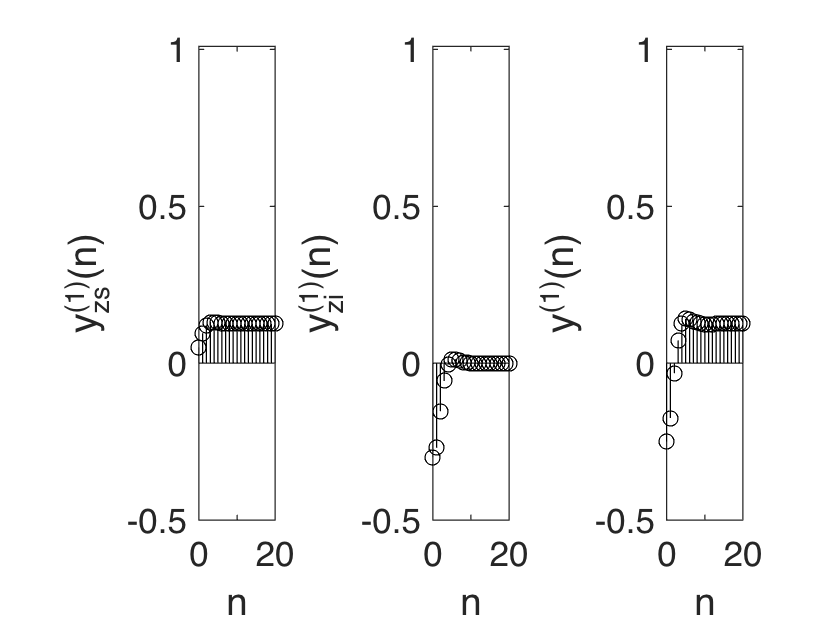

figure;
subplot(1,3,1), hold on, box on;
stem(n,yzs(:,1),'k');
set(gca,'FontSize',14,'XLim',[0,20],'YLim',[-0.5,1.01]);
xlabel('n');
ylabel('y_{zs}^{(1)}(n)');

subplot(1,3,2), hold on, box on;
stem(n,yzi(:,1),'k');
set(gca,'FontSize',14,'XLim',[0,20],'YLim',[-0.5,1.01]);
xlabel('n');
ylabel('y_{zi}^{(1)}(n)');

subplot(1,3,3), hold on, box on;
stem(n,y(:,1),'k');
set(gca,'FontSize',14,'XLim',[0,20],'YLim',[-0.5,1.01]);
xlabel('n');
ylabel('y^{(1)}(n)');

绘制第一种起始状态的三种响应

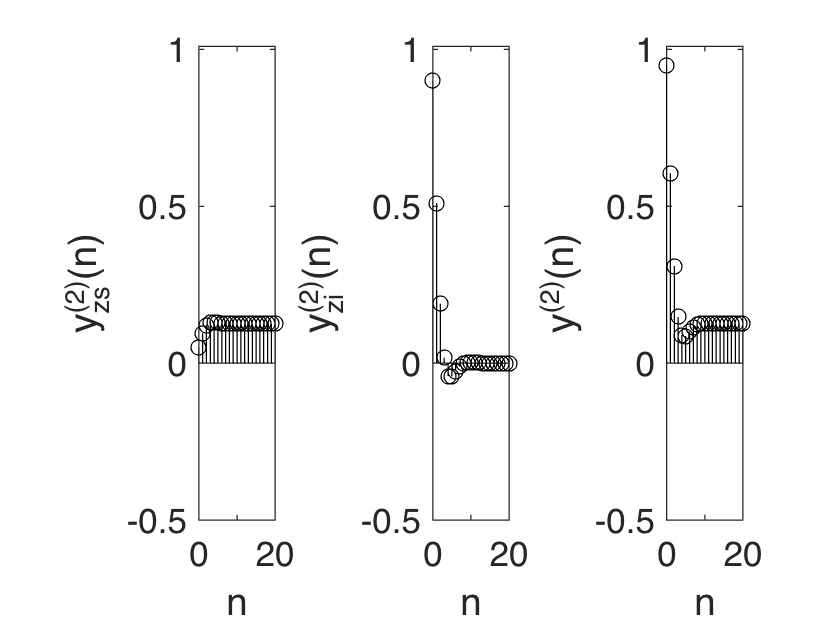

figure;
subplot(1,3,1), hold on, box on;
stem(n,yzs(:,2),'k');
set(gca,'FontSize',14,'XLim',[0,20],'YLim',[-0.5,1.01]);
xlabel('n');
ylabel('y_{zs}^{(2)}(n)');

subplot(1,3,2), hold on, box on;
stem(n,yzi(:,2),'k');
set(gca,'FontSize',14,'XLim',[0,20],'YLim',[-0.5,1.01]);
xlabel('n');
ylabel('y_{zi}^{(2)}(n)');

subplot(1,3,3), hold on, box on;
stem(n,y(:,2),'k');
set(gca,'FontSize',14,'XLim',[0,20],'YLim',[-0.5,1.01]);
xlabel('n');
ylabel('y^{(2)}(n)');